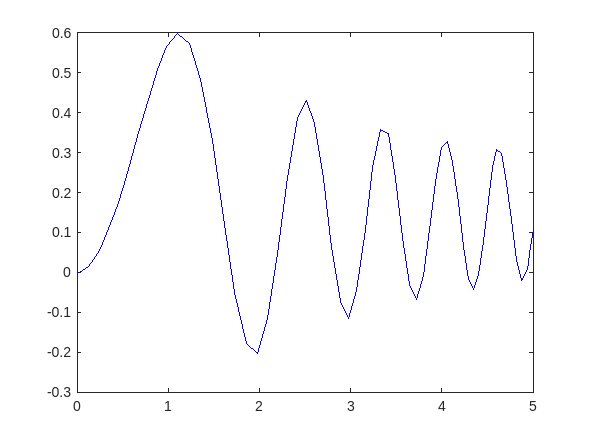

%x = ones(16,1);
x = [ones(8, 1); zeros(8, 1)];
%x = [ones(8, 1); -ones(8, 1)];
[tout, yout] = simTrajectoryTorque(x);
figure
plot(tout, yout(:,1), 'b-');

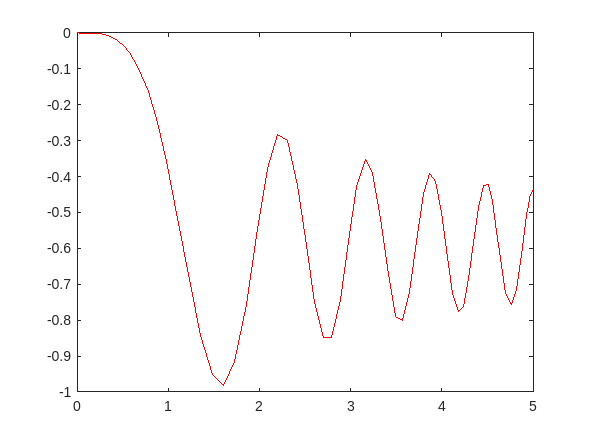

plot(tout, yout(:,2), 'r-');

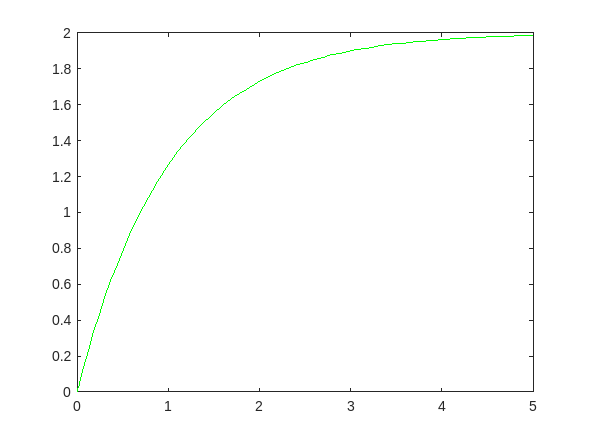

plot(tout, yout(:,3), 'g-');

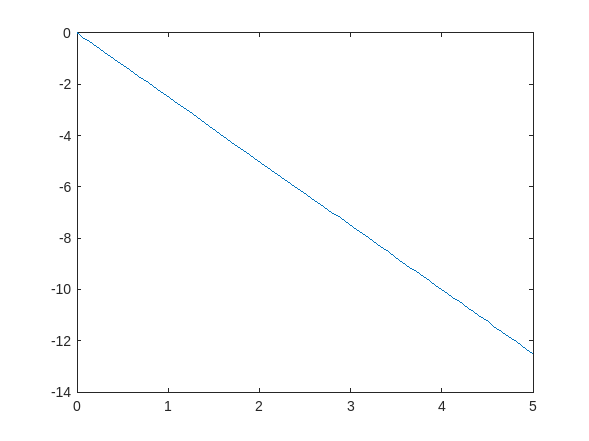

plot(tout, yout(:,5))

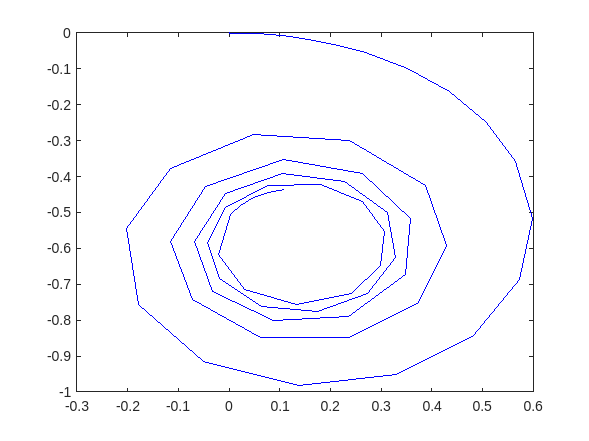

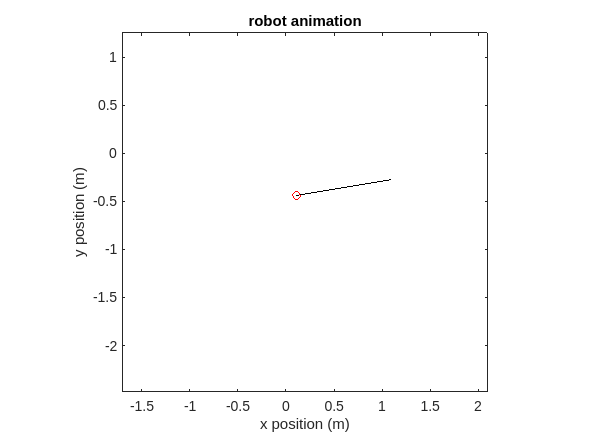

plot(yout(:,1), yout(:,2), 'b-');
animate_robot(tout, yout)

%{
syms L M d J R b
syms q [5 1]
syms u [2 1]

q_dot = [q(3)*cos(q(4));
         q(3)*sin(q(4));
         d*q(5)^2 + (u(2) + u(1))/(M*R) - b*q(3);
         q(5);
         L/(M*d^2 + J) * (u(2) - u(1))/R - M*d/(M*d^2 + J) * q(3)*q(5)]

$$q\_dot = \left(\begin{array}{c} q_{3}\,\cos\left(q_{4}\right)\\ q_{3}\,\sin\left(q_{4}\right)\\ d\,{q_{5}}^{2}-b\,q_{3}+\frac{u_{1}+u_{2}}{M\,R}\\ q_{5}\\ -\frac{L\,\left(u_{1}-u_{2}\right)}{R\,\left(M\,d^{2}+J\right)}-\frac{M\,d\,q_{3}\,q_{5}}{M\,d^{2}+J} \end{array}\right)$$

matlabFunction(q_dot, "File", "odefun_torque.m", "Vars", {q, u, L, M, d, J, R, b})

ans = function_handle with value:
    @odefun_torque


%}

function animate_robot(ts, ys)
    FPS = 20;

    % make time sequence
    t_anim = 0:1/FPS:ts(end);

    % interpolate x, y, theta at each frame
    x_anim = interp1(ts, ys(:, 1), t_anim);
    y_anim = interp1(ts, ys(:, 2), t_anim);
    theta_anim = interp1(ts, ys(:,4), t_anim);

    subplot(2,2,1:4)
    for iter = 1:numel(t_anim) % Animation loop
        cla
        hold on
        title('robot animation')
        arrow = [0 0; cos(theta_anim(iter)) sin(theta_anim(iter))];

        % Plot the direction arrow
        plot(arrow(:, 1) + x_anim(iter), arrow(:, 2) + y_anim(iter), 'k-')
        % Plot the robot
        plot(x_anim(iter), y_anim(iter), 'ro')

        hold off
        axis equal
        axis([min(ys(:,1))-1.5 max(ys(:,1))+1.5 min(ys(:,2))-1.5 max(ys(:,2)) + 1.25])
        xlabel('x position (m)')
        ylabel('y position (m)')
        % Forces the animation to plot mid-loop
        drawnow
    end
end